# Plots Energy prices for the UK

Source: https://nic.org.uk/data/all-data/historic-energy/#tab-renewable-sources-electricity

Year=1990:2019

Year =         1990        1991        1992        1993        1994        1995        1996        1997        1998        1999        2000        2001        2002        2003        2004        2005        2006        2007        2008        2009        2010        2011        2012        2013        2014        2015        2016        2017        2018        2019


Electricity_Price=[74.24	77.18	78.26	76.77	77.46	75.89	73.75	68.09	62.83	61.09	58.12	56.58	55.95	54.93	56.50	60.81	71.69	74.27	82.56	86.75	80.85	82.44	84.43	87.97	90.70	89.53	87.76	90.44	95.08	99.42]

Electricity_Price =    74.2400   77.1800   78.2600   76.7700   77.4600   75.8900   73.7500   68.0900   62.8300   61.0900   58.1200   56.5800   55.9500   54.9300   56.5000   60.8100   71.6900   74.2700   82.5600   86.7500   80.8500   82.4400   84.4300   87.9700   90.7000   89.5300   87.7600   90.4400   95.0800   99.4200


% Price in Pounds
Coal=[	17.11	17.21	17.23	17.04	17.71	17.41	17.16	16.78	16.37	16.45	16.24	16.72	17.29	17.17	17.53	18.78	19.57	20.10	23.03	27.20	26.00	25.93	26.01	25.61	25.74	25.53	25.04	24.73	24.35	24.61]

Coal =    17.1100   17.2100   17.2300   17.0400   17.7100   17.4100   17.1600   16.7800   16.3700   16.4500   16.2400   16.7200   17.2900   17.1700   17.5300   18.7800   19.5700   20.1000   23.0300   27.2000   26.0000   25.9300   26.0100   25.6100   25.7400   25.5300   25.0400   24.7300   24.3500   24.6100


Electricity=[		74.24	77.18	78.26	76.77	77.46	75.89	73.75	68.09	62.83	61.09	58.12	56.58	55.95	54.93	56.50	60.81	71.69	74.27	82.56	86.75	80.85	82.44	84.43	87.97	90.70	89.53	87.76	90.44	95.08	99.42]

Electricity =    74.2400   77.1800   78.2600   76.7700   77.4600   75.8900   73.7500   68.0900   62.8300   61.0900   58.1200   56.5800   55.9500   54.9300   56.5000   60.8100   71.6900   74.2700   82.5600   86.7500   80.8500   82.4400   84.4300   87.9700   90.7000   89.5300   87.7600   90.4400   95.0800   99.4200


Gas=[		18.60	18.79	18.07	17.11	17.71	17.70	17.29	16.60	15.51	15.18	14.38	14.51	15.18	15.02	15.66	17.47	22.33	23.07	26.57	30.37	27.31	28.72	30.80	32.24	32.98	31.17	28.80	27.44	27.54	26.70]

Gas =    18.6000   18.7900   18.0700   17.1100   17.7100   17.7000   17.2900   16.6000   15.5100   15.1800   14.3800   14.5100   15.1800   15.0200   15.6600   17.4700   22.3300   23.0700   26.5700   30.3700   27.3100   28.7200   30.8000   32.2400   32.9800   31.1700   28.8000   27.4400   27.5400   26.7000


Petroleum=[		49.62	45.07	38.26	39.98	39.07	37.76	40.58	38.33	31.06	34.22	46.61	44.58	41.37	44.58	49.25	61.45	67.42	65.21	90.54	69.78	85.03	101.02	100.50	97.83	87.13	64.37	58.41	69.13	81.67	78.82]

Petroleum =    49.6200   45.0700   38.2600   39.9800   39.0700   37.7600   40.5800   38.3300   31.0600   34.2200   46.6100   44.5800   41.3700   44.5800   49.2500   61.4500   67.4200   65.2100   90.5400   69.7800   85.0300  101.0200  100.5000   97.8300   87.1300   64.3700   58.4100   69.1300   81.6700   78.8200


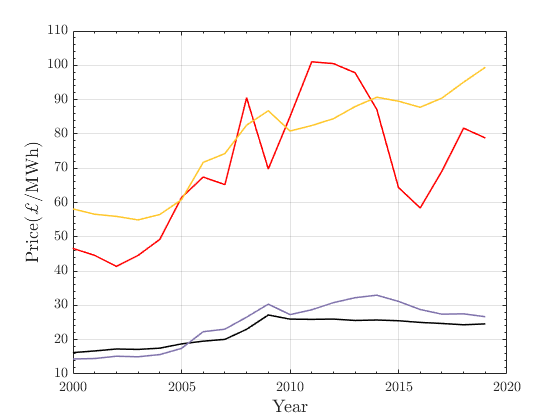

Color=[85,200,60       % Biomass 0,104,55  
      55,55,55          % Fossil
      202,0,32          % Geothermal
      33,102,172        % Hydro
      128,115,172        % Nuclear
      255,199,44      % Solar 244,109,67 
      146,197,222]/255; % Wind 
figure
plot(Year,Coal,"Color",'k','LineWidth',1.5)
hold on
plot(Year,Petroleum,"Color",'r','LineWidth',1.5)
plot(Year,Gas,"Color",Color(5,:),'LineWidth',1.5)
plot(Year,Electricity,"Color",Color(6,:),'LineWidth',1.5)
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

text(23,0.33,'Caceres','Color',[0 0 0],'Interpreter','latex','FontSize',18)
ylabel('Price($\pounds$/MWh)','Interpreter','latex','FontSize',18)
xlabel('Year','Interpreter','latex','FontSize',18)
xlim([2000 2020])
% ylim([0.3 1])
print('-dpdf','-r400','Price.pdf')

Wind=[	9187.70	8606.20	32564.00	217364.70	343433.90	392279.90	487762.20	666980.50	876902.00	850153.00	945984.20	964941.10	1256040.00	1285347.60	1934999.40	2903894.70	4225062.70	5273856.10	7121514.20	9281088.90	10285804.60	15963105.40	19847292.80	28397203.60	31959472.60	40274922.60	37155175.10	49633234.70	56904310.70]

Wind = 	1.0e+07 *

    0.0009    0.0009    0.0033    0.0217    0.0343    0.0392    0.0488    0.0667    0.0877    0.0850    0.0946    0.0965    0.1256    0.1285    0.1935    0.2904    0.4225    0.5274    0.7122    0.9281    1.0286    1.5963    1.9847    2.8397    3.1959    4.0275    3.7155    4.9633    5.6904


Hydro=[	5206285.80	4623622.80	5431093.70	4301588.10	5093474.80	4837382.20	3392238.40	4168657.20	5117316.30	5335844.00	5085333.80	4055729.90	4787954.70	3137541.40	4843895.00	4921467.10	4593035.90	5077425.40	5141274.10	5228033.90	3591344.00	5691722.00	5309676.50	4701427.50	5887803.80	6297296.10	5393877.70	5901643.50	5489825.20]

Hydro = 	1.0e+06 *

    5.2063    4.6236    5.4311    4.3016    5.0935    4.8374    3.3922    4.1687    5.1173    5.3358    5.0853    4.0557    4.7880    3.1375    4.8439    4.9215    4.5930    5.0774    5.1413    5.2280    3.5913    5.6917    5.3097    4.7014    5.8878    6.2973    5.3939    5.9016    5.4898


Solar=[	0.00	0.00	0.00	0.00	0.00	0.00	0.00	0.00	0.00	0.00	1279.30	1860.80	2674.90	2907.50	3954.20	8141.00	10699.60	13956.00	16979.80	20003.60	40239.80	243648.50	1353732.00	2010129.20	4054101.70	7532867.30	10407919.60	11475553.60	12857430.20]

Solar = 	1.0e+07 *

         0         0         0         0         0         0         0         0         0         0    0.0001    0.0002    0.0003    0.0003    0.0004    0.0008    0.0011    0.0014    0.0017    0.0020    0.0040    0.0244    0.1354    0.2010    0.4054    0.7533    1.0408    1.1476    1.2857


Biofuels=[2547202.60	2871214.40	3891863.20	5140111.10	6405920.30	6847046.20	7432500.40	8848569.20	10908940.00	13898198.90	16064635.30	18775355.70	19724945.20	22780844.00	25496797.90	26483254.50	27301076.10	29572647.70	31817121.40	35682003.00	38274795.20	39789835.30	46968452.80	57936008.00	70728310.20	85699725.50	90234844.00	94832299.30	104158396.30]

Biofuels = 	1.0e+08 *

    0.0255    0.0287    0.0389    0.0514    0.0641    0.0685    0.0743    0.0885    0.1091    0.1390    0.1606    0.1878    0.1972    0.2278    0.2550    0.2648    0.2730    0.2957    0.3182    0.3568    0.3827    0.3979    0.4697    0.5794    0.7073    0.8570    0.9023    0.9483    1.0416


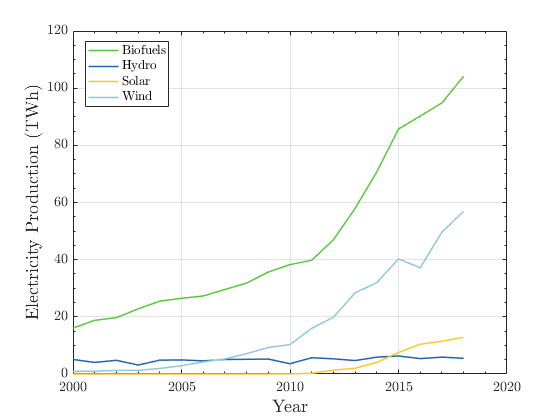

figure
plot(Year(1:29),Biofuels/1e6,"Color",Color(1,:),'LineWidth',1.5)
hold on
plot(Year(1:29),Hydro/1e6,"Color",Color(4,:),'LineWidth',1.5)
plot(Year(1:29),Solar/1e6,"Color",Color(6,:),'LineWidth',1.5)
plot(Year(1:29),Wind/1e6,"Color",Color(7,:),'LineWidth',1.5)
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
legend('Biofuels','Hydro','Solar','Wind','location','best','interpreter','latex')

ylabel('Electricity Production (TWh)','Interpreter','latex','FontSize',18)
xlabel('Year','Interpreter','latex','FontSize',18)
xlim([2000 2020])
% ylim([0.3 1])
print('-dpdf','-r400','Electricity.pdf')

## Cost PV

[https://www.gov.uk/government/statistics/solar-pv-cost-data](https://www.gov.uk/government/statistics/solar-pv-cost-data)


FY=2014:2022

FY =         2014        2015        2016        2017        2018        2019        2020        2021        2022


Cost_PV=[2080.00 2070.32 1832.82 1865.96 1839.96 1815.87 1562.21 1628.13 1875.54]

Cost_PV = 	1.0e+03 *

    2.0800    2.0703    1.8328    1.8660    1.8400    1.8159    1.5622    1.6281    1.8755


C_4=[1640.00	1609.97	1459.95	1505.40	1509.46	1498.28	1703.87	1685.08	1604.87]

C_4 = 	1.0e+03 *

    1.6400    1.6100    1.4600    1.5054    1.5095    1.4983    1.7039    1.6851    1.6049


C_10=[1390.00	1385.34	1265.30	1229.83	1152.90	1138.94	1076.79	1087.77	1131.87]

C_10 = 	1.0e+03 *

    1.3900    1.3853    1.2653    1.2298    1.1529    1.1389    1.0768    1.0878    1.1319


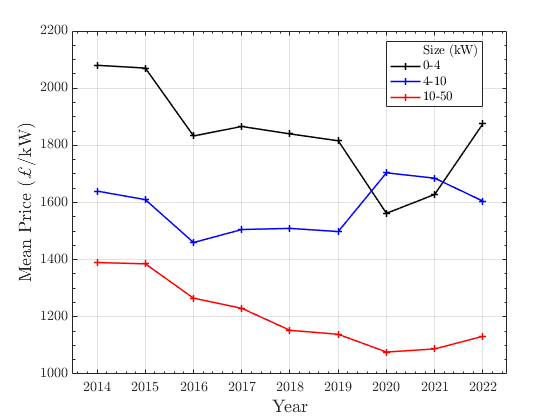

figure
plot(nan,nan,'color','none')
hold on
plot(FY,Cost_PV,'-+k','LineWidth',1.5)

plot(FY,C_4,'-+b','LineWidth',1.5)
plot(FY,C_10,'-+r','LineWidth',1.5)
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

text(23,0.33,'Caceres','Color',[0 0 0],'Interpreter','latex','FontSize',18)
ylabel(' Mean Price ($\pounds$/kW)','Interpreter','latex','FontSize',18)
xlabel('Year','Interpreter','latex','FontSize',18)
xlim([2013.5 2022.5])
legend('Size (kW)','0-4','4-10','10-50','location','best','interpreter','latex')
% ylim([0.3 1])
print('-dpdf','-r400','PV_Cost.pdf')